% house_simulate(timespan, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation)
[T, Y, debug] = house_simulate([1, 24 * 60 * 60], 5, 10, 25, 1, 0.5)

T = 	1.0e+04 *

    0.0001
    0.0448
    0.0894
    0.1341
    0.1787
    0.2056
    0.2324
    0.2593
    0.2861
    0.3130


Y =   291.0000  291.0000
  290.7791  291.0741
  290.7677  291.1479
  291.2394  291.2209
  291.5288  291.2943
  291.3754  291.3391
  291.3214  291.3838
  291.3943  291.4283
  291.4676  291.4728
  291.4606  291.5176


debug = 	1.0e+06 *

         0         0         0         0
         0    0.0001         0    0.0097
    0.0001    0.0002         0    0.0097
   -0.0002    0.0002    0.0000    0.0097
    0.0209    0.0002   -0.0008    0.0101
    0.1835    0.0002   -0.0068    0.0101
    0.9598    0.0004   -0.0358    0.0102
   -1.6343   -0.0001    0.0610    0.0102
    0.0000    0.0002         0    0.0097
    0.0000    0.0002    0.0000    0.0097


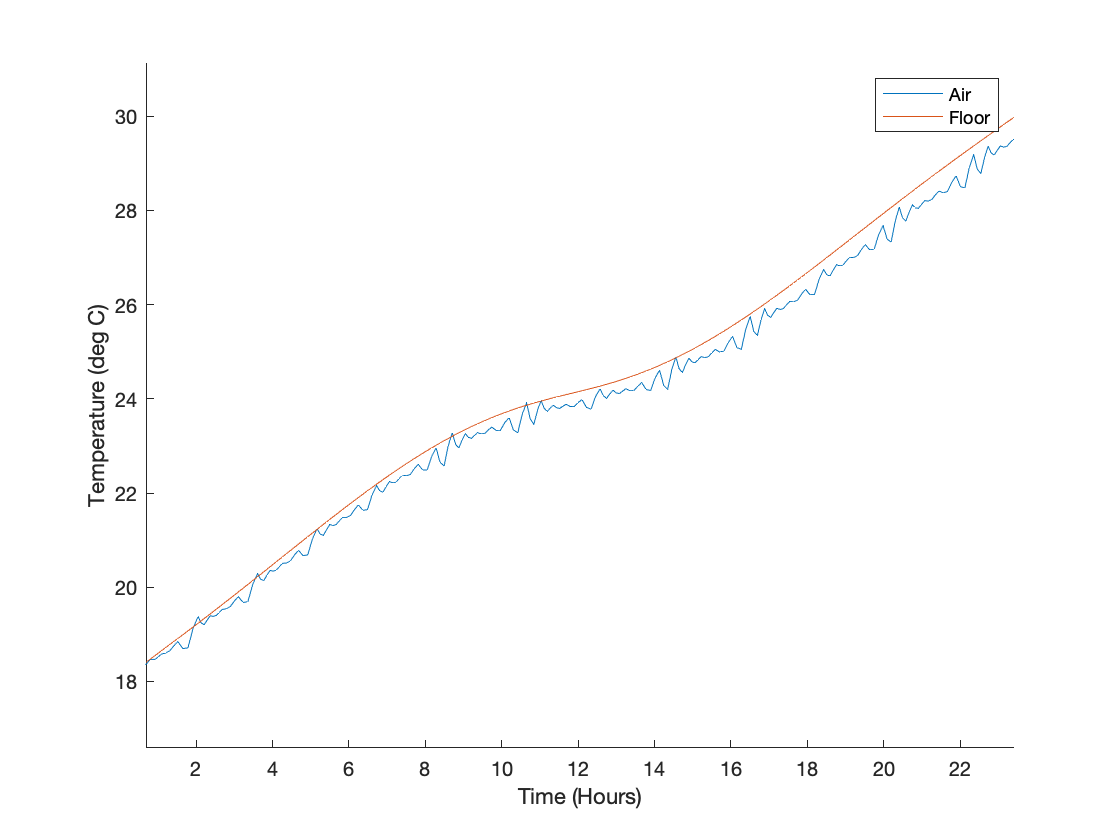

clf; hold on;

plot(T / (60 * 60), Y(:, 1) - 273);
plot(T / (60 * 60), Y(:, 2) - 273);
legend("Air", "Floor");
xlabel("Time (Hours)");
ylabel("Temperature (deg C)");

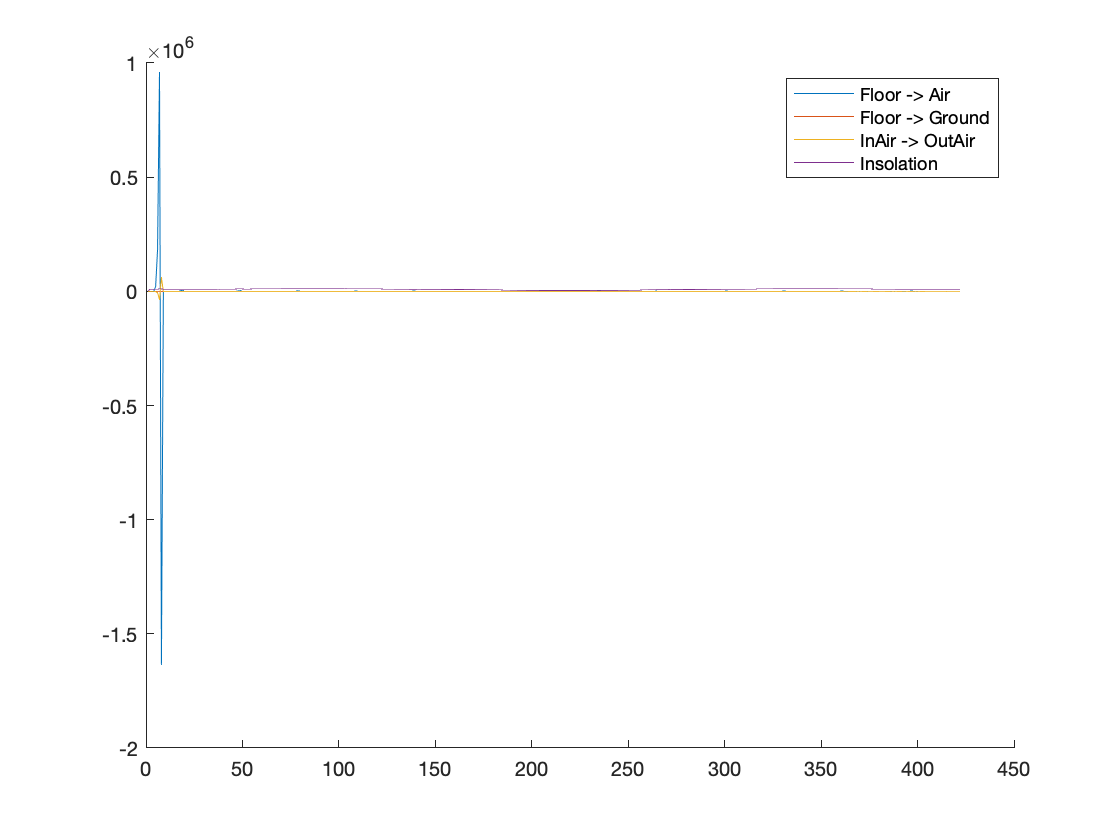

figure; clf; hold on;
%        debug(end + 1, :) = [dUdt_floor_to_air, dUdt_floor_to_ground, dUdt_air_to_air, dUdt_insolation];
plot(debug(:, 1));
plot(debug(:, 2));
plot(debug(:, 3));
plot(debug(:, 4));
legend("Floor -> Air", "Floor -> Ground", "InAir -> OutAir", "Insolation");